## Analysis of Data from the PPG Sensor and EDA sensor 

In this document, we aim to compare the results of the ppg sensor and the eda sensor, both under induced stress, and under calm conditions. The method of induced stress was as follows:

- Start from a number (e.g. 1000)

- Repeatedly subtract a random number (i.e. 17)

This method of mental arithmetic known as Serial Subtraction is used as part of the Trier Social Stress test, but in this test, we only used the serial subtraction due to it being a prototype and having limited time. We predict that RMSSD and SDNN will be slightly lower during stress, compared to under calm conditions, but the average heart rate will be insignificantly different. For the EDA, we predict that resistance (since our sensor measures resistance rather than conductivity) will decrease under stress, as conductivity increases, from more sweat.

filename = "red_data_calm_eda+ppg.txt";
fid = fopen(filename, "r");

window_count = 0;

bpm_all_calm = [];
sdnn_all_calm = [];
rmssd_all_calm = [];
gsr_all_calm = [];
sigma_gsr_all_calm = [];
mad_gsr_all_calm = [];

while ~feof(fid)
    % read 3 lines
    % first line is ppg
    % second line is time
    % third line is index of peaks
    ppg_line = fgetl(fid);
    time_line = fgetl(fid);
    peak_line = fgetl(fid);
    gsr_line = fgetl(fid);


    if ~ischar(peak_line)
        break;
    end
    ppg = str2double(strsplit(ppg_line, ','));
    times = str2double(strsplit(time_line, ','));
    peaks = str2double(strsplit(peak_line, ','));
    gsr = str2double(strsplit(gsr_line, ','));


    window_count = window_count + 1;
    peak_times = times(peaks + 1);
    
    if length(peak_times) > 1
        rr = diff(peak_times) / 1000;
        bpm = 60 / mean(rr);
        sdnn = std(rr);
        rmssd = sqrt(mean(diff(rr).^2));
        if (isnan(rmssd))
            continue
        end
        bpm_all_calm(end+1) = bpm;
        sdnn_all_calm(end+1) = sdnn;
        rmssd_all_calm(end+1) = rmssd;
    end
    gsr_all_calm(end+1) = mean(gsr);
    sigma_gsr_all_calm(end+1) = std(gsr, 1);
    dx = diff(gsr);
    dt = diff(times);
    mean_absolute_derivative = mean(abs(dx ./ dt));
    mad_gsr_all_calm(end+1) = mean_absolute_derivative;
end
fclose(fid);


% now repeat for stress
filename = "red_data_stress_eda+ppg.txt";
fid = fopen(filename, "r");

window_count = 0;

bpm_all_stress = [];
sdnn_all_stress = [];
rmssd_all_stress = [];
gsr_all_stress = [];
sigma_gsr_all_stress = [];
mad_gsr_all_stress = [];

while ~feof(fid)
    % read 3 lines
    % first line is ppg
    % second line is time
    % third line is index of peaks
    ppg_line = fgetl(fid);
    time_line = fgetl(fid);
    peak_line = fgetl(fid);
    gsr_line = fgetl(fid);

    if ~ischar(peak_line)
        break;
    end
    ppg = str2double(strsplit(ppg_line, ','));
    times = str2double(strsplit(time_line, ','));
    peaks = str2double(strsplit(peak_line, ','));
    gsr = str2double(strsplit(gsr_line, ','));

    window_count = window_count + 1;
    peak_times = times(peaks + 1);
    
    if length(peak_times) > 1
        rr = diff(peak_times) / 1000;
        bpm = 60 / mean(rr);
        sdnn = std(rr);
        rmssd = sqrt(mean(diff(rr).^2));
        if (isnan(rmssd))
            continue
        end
        bpm_all_stress(end+1) = bpm;
        sdnn_all_stress(end+1) = sdnn;
        rmssd_all_stress(end+1) = rmssd;
    end
    gsr_all_stress(end+1) = mean(gsr);
    sigma_gsr_all_stress(end+1) = std(gsr, 1);
    dx = diff(gsr);
    dt = diff(times);
    mean_absolute_derivative = mean(abs(dx ./ dt));
    mad_gsr_all_stress(end+1) = mean_absolute_derivative;
end
fclose(fid);

mean_bpm_calm = mean(bpm_all_calm);
mean_bpm_stress = mean(bpm_all_stress);

mean_sdnn_calm = mean(sdnn_all_calm);
mean_sdnn_stress = mean(sdnn_all_stress);

mean_rmssd_calm = mean(rmssd_all_calm);
mean_rmssd_stress = mean(rmssd_all_stress);

mean_gsr_calm = mean(gsr_all_calm);
mean_gsr_stress = mean(gsr_all_stress);

std_gsr_calm = mean(sigma_gsr_all_calm);
std_gsr_stress = mean(sigma_gsr_all_stress);

mad_gsr_calm = mean(mad_gsr_all_calm);
mad_gsr_stress = mean(mad_gsr_all_stress);

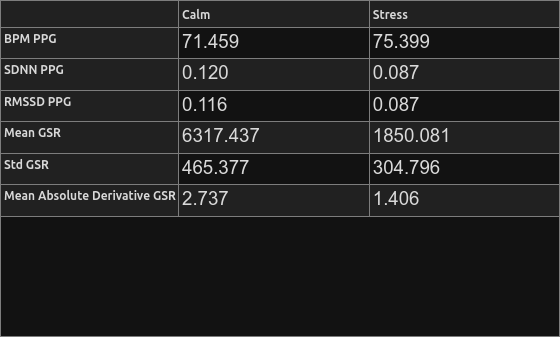

Feature = ["BPM PPG";
           "SDNN PPG";
           "RMSSD PPG";
           "Mean GSR";
           "Std GSR";
           "Mean Absolute Derivative GSR"];

Calm = round([mean_bpm_calm;
              mean_sdnn_calm;
              mean_rmssd_calm;
              mean_gsr_calm;
              std_gsr_calm;
              mad_gsr_calm],3);

Stress = round([mean_bpm_stress;
                mean_sdnn_stress;
                mean_rmssd_stress;
                mean_gsr_stress;
                std_gsr_stress;
                mad_gsr_stress],3);
Calm_str = compose("%.3f", Calm);
Stress_str = compose("%.3f", Stress);

Data = [Calm_str Stress_str];

f = figure('Name','Stress Detection Results','Color',[0.1 0.1 0.1]);

t = uitable(f,...
    'Data', Data,...
    'ColumnName', {'Calm','Stress'},...
    'RowName', Feature,...
    'Units','Normalized',...
    'Position',[0 0 1 1],...
    'FontSize', 14);

## Results of PPG and EDA

From these results, we can see that the mean RMSSD and mean SDNN under stress is indeed lower, signalling lower HRV (heart rate variability). This signals a sympathetic response ("fight or flight"), where heart rate rhythm actually becomes more regular and less variable. This showcases that our prediction is correct, and that our PPG sensor could have the potential to detect stress - which is great news. Also the heart rate does not seem to be affected that much by the stress induced - just a slight average increase, which is expected, especially for only mild cognitive stress.

Results of the EDA also follow predictions, as the mean gsr readings are lower under induced stress than under calm conditions. However, the mean absolute derivative (rate of change), and the mean standard deviation across all windows is actually lower under stress, which could signal. We have plotted the results below. It is important to notice, that our sensor does actually measure resistance not conductivity (it is the MAX30102 sensor)

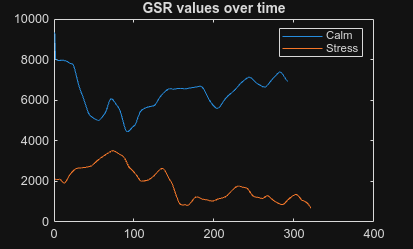

figure
plot(gsr_all_calm)
hold on
plot(gsr_all_stress)
legend("Calm", "Stress")
title("GSR values over time")
hold off

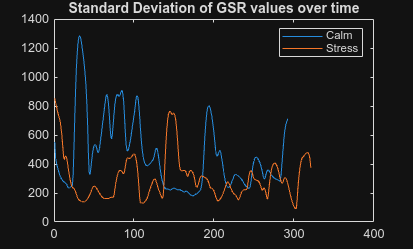

figure
plot(sigma_gsr_all_calm)
hold on
plot(sigma_gsr_all_stress)
legend("Calm", "Stress")
title("Standard Deviation of GSR values over time")
hold off

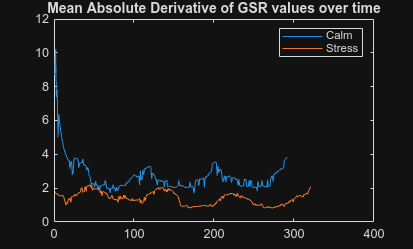

figure
plot(mad_gsr_all_calm)
hold on
plot(mad_gsr_all_stress)
legend("Calm", "Stress")
title("Mean Absolute Derivative of GSR values over time")
hold off

From these plots, we can see GSR values are claerly higher for calm conditions, but standard deviation and mean absolute derivative is only slightly higher on average than under stress. Combining all three however, could still yield a high accuracy, especially when combined with the PPG sensor.

Now lets plot for the PPG sensor

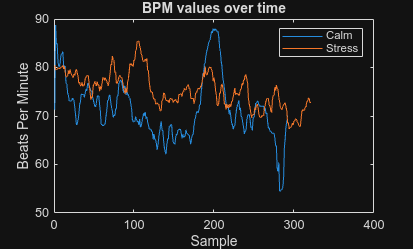

figure
plot(bpm_all_calm)
hold on
plot(bpm_all_stress)
legend("Calm", "Stress")
title("BPM values over time")
xlabel("Sample")
ylabel("Beats Per Minute")
hold off

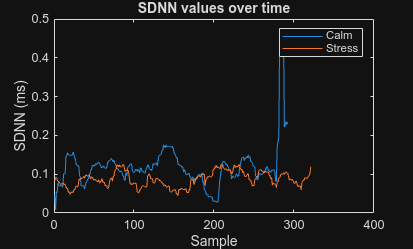

figure
plot(sdnn_all_calm)
hold on
plot(sdnn_all_stress)
legend("Calm", "Stress")
title("SDNN values over time")
xlabel("Sample")
ylabel("SDNN (ms)")
hold off

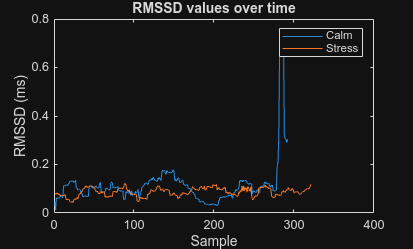

figure
plot(rmssd_all_calm)
hold on
plot(rmssd_all_stress)
legend("Calm", "Stress")
title("RMSSD values over time")
xlabel("Sample")
ylabel("RMSSD (ms)")
hold off

Here, we see again that BPM values over time are higher for stressed conditions than calm conditions for majority of the time, apart from some anomalies. RMSSD and SDNN values are typically only slightly higher for calm conditions, excluding the anomaly near the end of the calm samples. Combining these again with the EDA values could yield in a high accuracy for our model.